## **Pendolo smorzato**

 Per integrare il sistema cominciamo a defnire i parametri per una prima risoluzione:

m = 5 ;%kg
b = 0.6; %kg/s
l = 1; %m

Scegliamo ora l'intervallo di integrazione del tempo:

dt = [0:0.05:40]; %#ok<NBRAK> 

Inseriamo ora le condizioni iniziali del sistema, per questo primo esempio prendiamo la velocità nulla e lo spostamento iniziale di un piccolo angolo:

x0 = [pi/10,0];

Per concludere, impostiamo i parametri di tolleranza dell'algoritmo ode45:

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Possiamo finalmente chiamare il risolutore ode45 con la seguente sinassi:

[t,x] = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0,opts);	

Quello che ci viene restituito sono due grandezze, un vettore contenente gli istanti per i quali è stata calcolata la soluzione, e una matrice x che contiene per ogni istante di tempo il valore di x(1) e x(2), ossia theta e omega. 				

Andiamo a graficare il risultato: 			

figure;
plot(t,x(:,1),'k-',t,x( :,2),'r--');
grid;
title ('Andamento delle variabili di stato','FontSize',25);
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
legend('$\theta\,[rad]$','$\dot{\theta} [rad/s]$','Interpreter','latex');
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Aggiorniamo ora le condizioni iniziali per vedere il risultato da un diverso stato iniziale:

x0_2 = [pi/10,2];
[t,x2]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_2,opts);
figure;
plot(t,x(:,1),'r--',t,x2(:,1),'k-');
legend ('$\theta_1\,[rad]$','$\theta_2 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Se invece di modificare la velocità iniziale modifichiamo l'angolo di partenza lasciando la velocità uguale a zero otteniamo:

x0_3 = [pi/3,0];
[t,x3]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_3,opts);
figure;
plot(t,x(:,1),'r--',t,x3(:,1),'k-');
legend ('$\theta_1\,[rad]$','$\theta_3 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

### Studio Parametrico

Andiamo ora a modificare alcuni parametri impostati all'inizio dello studio per vedere come cambia la risposta del sistema.

l_2 = 10;%m

Avendo aggiornato il valore di l, rendendolo 10 volte più grande, andiamo a risolvere il sistema con le condizioni iniziali scelte all'inizio:

[t,x_4] = ode45(@(t,x)pendolo_smorzato(m,l_2,b,x,t),dt,x0,opts);	
figure;
plot(t,x_4(:,1),'k-',t,x(:,1),'r--');
title ('Andamento delle variabili di stato','FontSize',25);
legend('$\theta_4  [rad]$','$\theta [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14);
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);

Modificando ora invece di L, la grandezza m, proviamo a vedere la rispsota:

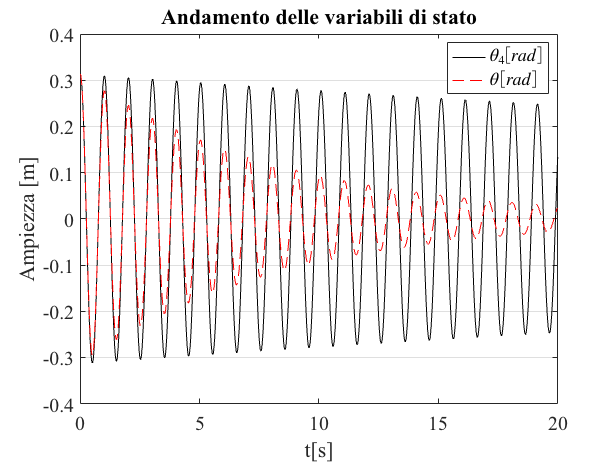

m_2 = 50;
[t,x_5] = ode45(@(t,x)pendolo_smorzato(m_2,l,b,x,t),dt,x0,opts);
plot(t,x_5(:,1),'k-',t,x(:,1),'r--');
title ('Andamento delle variabili di stato','FontSize',25);
legend('$\theta_4  [rad]$','$\theta [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14);
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',18);